# `Εργασία Γενετικών Αλγορίθμων - Άσκηση 3`

## `Θεωρητική ανάλυση προβλήματος`

`Το πρόβλημα χρησιμοποιεί γενετικούς αλγορίθμους για να βρει λύσεις μιας τριτοβάθμιας πολυωνυμικής εξίσωσης. Η εξίσωση είναι η εξής και οι λύσεις της βρίσκονται σε διάστημα [-10,10].`

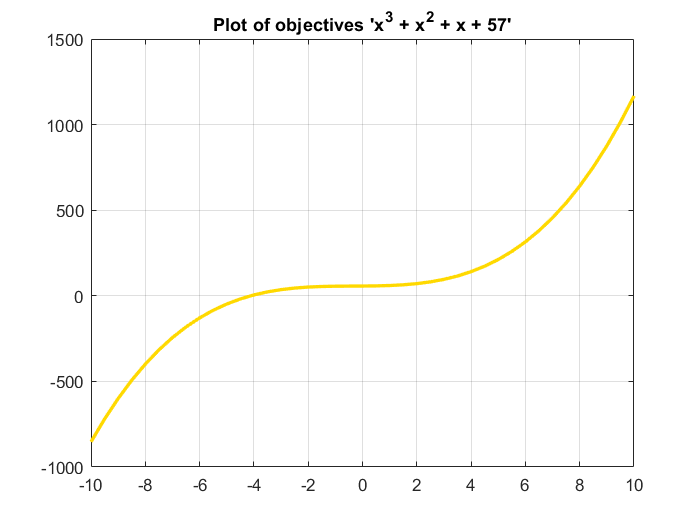

x_t = -10:0.5:10;
func_to_plot = x_t.^(3) + x_t.^(2) + x_t + 57;
plot(x_t, func_to_plot, 'LineWidth', 2, 'Color', [1 0.85 0])
title('Plot of objectives ''x^3 + x^2 + x + 57''');
grid on

`Αντίστοιχα δημιουργούμε την παραπάνω συνάρτηση σε νέο αρχείο και θα παρουσιαστεί η διαδικασία με δύο τρόπους. Αρχικά χωρίς την χρήση του "``optimization tool``" μέσω του κώδικα και έπειτα με την χρήση του εργαλείου. Εισάγω την συνάρτηση στον κώδικα μου όπως γράφτηκε παραπάνω αλλά σε αρχείο συνάρτησης. Η συνάρτηση είναι γραμμένη με τρόπο ώστε να βρεθούν λύσεις στα καθορισμένα όρια. Στην συνέχεια θα προβληθούν τα σετ των λύσεων γνωστά ως "Pareto form".`

clc; clear;
disp("This is the function used for Multiobjective Optimization Problem:")

This is the function used for Multiobjective Optimization Problem:


type Equation_fitness.m;


function y = Equation_fitness(x) 
    y = x.^(3) + x.^(2) + x + 57;
end



`Η παραπάνω συνάρτηση έχει μια είσοδο όσες και οι μεταβλητές στο πρόβλημά μας. Η "fitness" συνάρτηση υπολογίζει την τιμή κάθε συνάρτησης, στον προκειμένη μιας, και επιστρέφει ένα διάνυσμα λύσεων, σε αυτή την περίπτωση τρεις λύσεις. Ορίζω τα όρια λύσεων και τον αριθμό λύσεων.`

FitnessFcn = @Equation_fitness; 

nvars = 3;

lb = [-10 -10 -10]; ub = [10 10 10];

`Σε αυτό το σημείο γίνεται χρήση του εργαλείου "``gamultiobj``" έναντι του "``optimization tool``". Αποθηκεύονται οι είσοδοι, οι έξοδοι ο λόγος τερματισμού και το αποτέλεσμα κατά σειρά στις παρακάτω μεταβλητές. Συγκεκριμένα στις δύο ρυθμίσεις οπτικοποιώ τα σετ των λύσεων για την μια συνάρτηση που σε κάθε γενιά, στο πρώτο διάγραμμα, και την διαφορετικότητα των λύσεων στο δεύτερο διάγραμμα. Επιπλέον έχουμε ρυθμίσει τα κριτήρια για τον τερματισμό του αλγόριθμου και εμφανίζονται ως πληροφορίες παρακάτω. `

options = optimoptions(@gamultiobj,'PlotFcn',{@gaplotpareto,@gaplotscorediversity});

`Για παράδειγμα ο πλυθησμός ρυθμίστηκε στους 200 αντι για 50 που είναι συνήθως για αριθμό μεταβλητών μικρότερο του 5.`

options.PopulationSize = 200;

options =   gamultiobj options:

   Set properties:
                    PlotFcn: {@gaplotpareto  @gaplotscorediversity}
             PopulationSize: 200

   Default properties:
        ConstraintTolerance: 1.0000e-03
                CreationFcn: @gacreationuniform
               CrossoverFcn: @crossoverintermediate
          CrossoverFraction: 0.8000
                    Display: 'final'
         DistanceMeasureFcn: {@distancecrowding  'phenotype'}
          FunctionTolerance: 1.0000e-04
                  HybridFcn: []
    InitialPopulationMatrix: []
     InitialPopulationRange: []
        InitialScoresMatrix: []
             MaxGenerations: '200*numberOfVariables'
        MaxStallGenerations: 100
                    MaxTime: Inf
                MutationFcn: @mutationadaptfeasible
                  OutputFcn: []
             ParetoFraction: 0.3500
             PopulationType: 'doubleVec

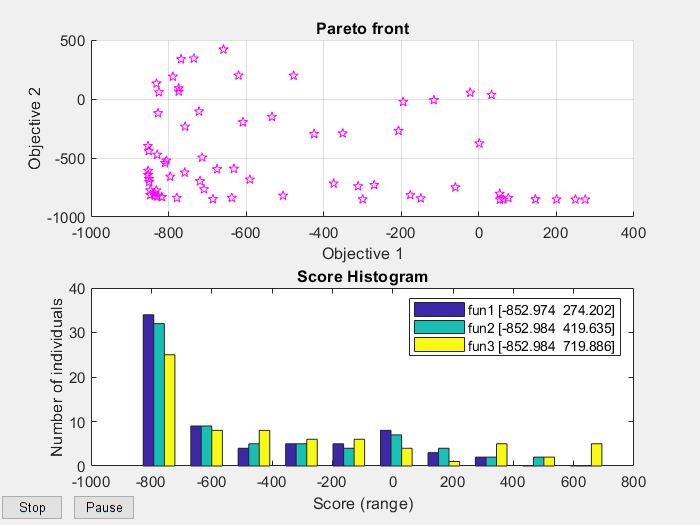

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


x =    -1.4654   -9.9999   -8.2534
   -9.2518    6.7645   -9.9936
   -9.9999   -7.9994    6.1892
   -9.9990   -9.1899    7.4088
   -8.9569   -9.3497   -9.3932
   -9.9067   -5.9093   -6.7436
   -3.1406   -3.0629   -9.9999
   -9.7659    4.7181   -9.9730
   -9.9145   -9.9014    8.3600
   -7.4688   -9.5773   -9.3315


fval =    54.5353 -852.9838 -445.3463
 -658.5798  419.0567 -851.1940
 -852.9737 -398.8988  338.5836
 -852.7301 -643.8608  525.9751
 -590.3118 -682.2522 -692.9547
 -827.0352 -120.3432 -210.9448
   32.7455   34.5855 -852.9840
 -788.8046  189.0055 -845.4389
 -829.1793 -825.5698  719.5268
 -311.3201 -739.3173 -677.8108


exitflag = 1

output = struct with fields:
        problemtype: 'boundconstraints'
           rngstate: [1×1 struct]
        generations: 120
          funccount: 24000
            message: 'Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.'
      maxconstraint: 0
    averagedistance: 0.0401
             spread: 0.1133


population =    -9.8711   -9.9024    8.4888
   -1.4654   -9.9999   -8.2534
   -8.3922    6.0532   -9.9760
   -9.2518    6.7645   -9.9936
   -9.9999   -7.9994    6.1892
   -1.4644   -9.9999   -8.2534
   -9.5908    6.7203   -9.9285
    5.6830   -9.9956   -8.3673
   -1.4642   -9.9999   -8.2534
   -9.8711   -9.9024    8.4887


score =  -817.2634 -825.8458  749.2603
   54.5353 -852.9838 -445.3463
 -472.0200  321.4907 -846.2698
 -658.5798  419.0567 -851.1940
 -852.9737 -398.8988  338.5836
   54.5397 -852.9838 -445.3463
 -742.8061  412.3811 -833.0598
  278.5226 -851.7763 -467.1654
   54.5408 -852.9666 -445.3463
 -817.2634 -825.8458  749.2317


[x, fval, exitflag, output, population, score] = gamultiobj(FitnessFcn, nvars, [], [], [], [], lb, ub, options)

disp('The number of points on the Pareto front was:' ); size(x,1)

The number of points on the Pareto front was:


ans = 70

disp('The number of population was:' ); options.PopulationSize

The number of population was:


ans = 200

`Σε αυτό το σημείο γίνεται χρήση του εργαλείου "``optimization tool``" και προβάλλονται τα αποτελέσματα.`

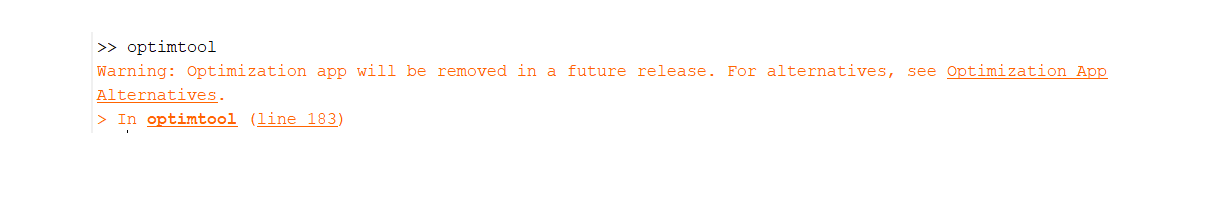

imshow("optimtool_1.PNG")

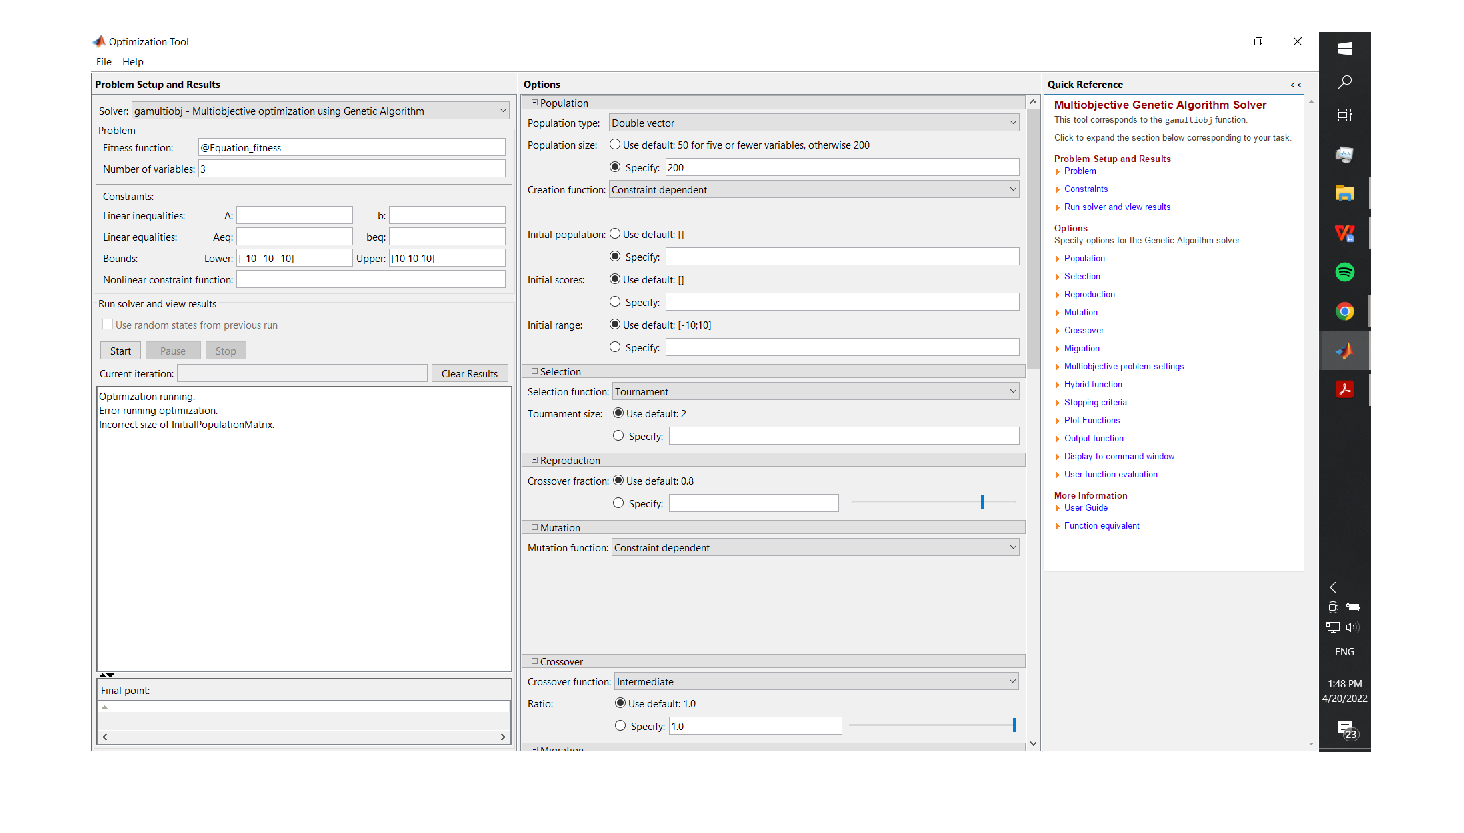

imshow("optimtool_2.PNG")

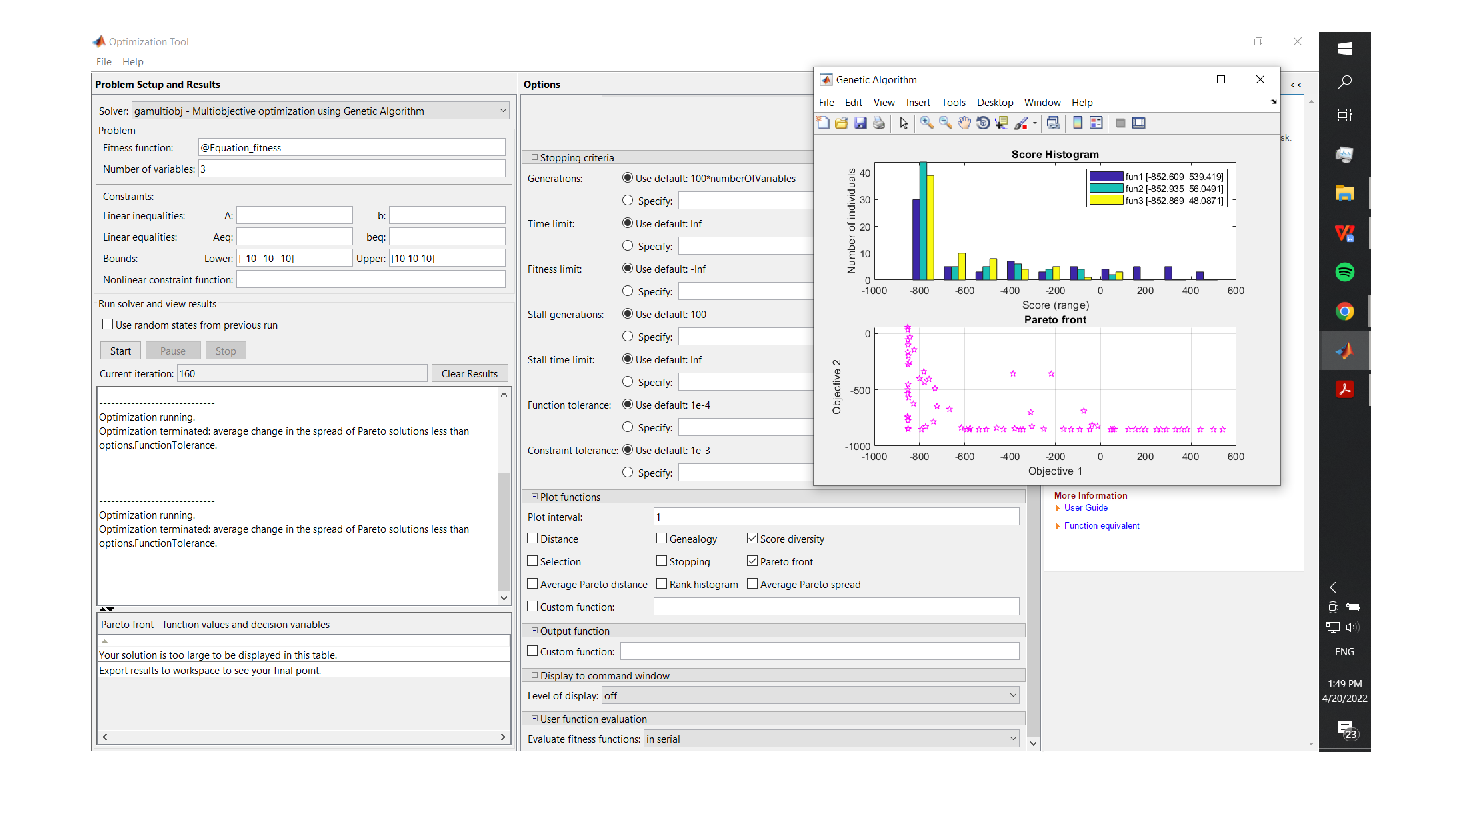

imshow("optimtool_3.PNG")

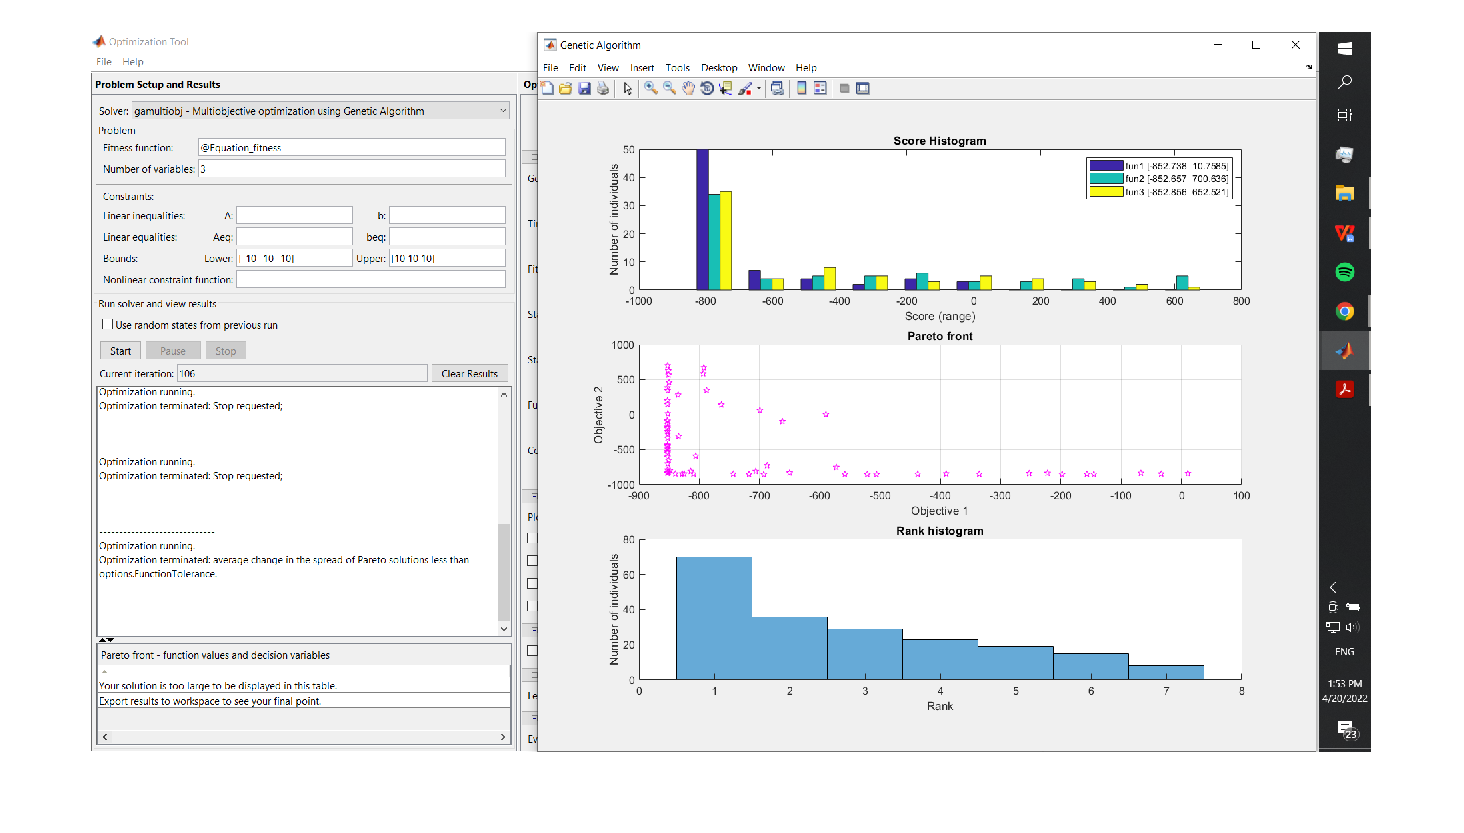

imshow("optimtool_4.PNG")